# **LAB-4: denoising by spectral substraction**

SNRdB = @(s,n)( 10*log10(sum(s(:).^2)/sum((n(:)-s(:)).^2)));
[ music, fs_m] = audioread( 'audios/music.wav' );
[ noise1, fs_1] = audioread( 'audios/noise1.wav' );
[ noise2, fs_2] = audioread( 'audios/noise2.wav' );
[ noise3, fs_3] = audioread( 'audios/noise3.wav' );


    % desired SNR level (dB)
    snr = 4; 

    % get mixture speech at a desired SNR level
    noisy = addnoise( music, noise1, snr );

Add noise to signal at a prescribed SNR level.

    % compare true and desired SNRs
    fprintf( ' Desired SNR: %0.2f dB\n', snr );

 Desired SNR: 4.00 dB


    fprintf( 'Measured SNR: %0.2f dB\n', SNRdB(music,noisy) );

Measured SNR: 4.00 dB


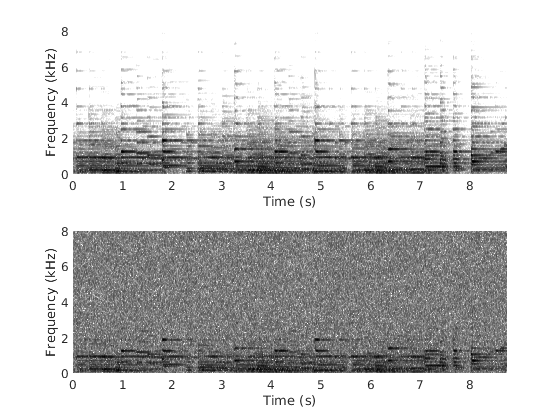

    
% plot time domain waveforms
    subplot( 2,1,1 ); hold on;
    myspectrogram( music, fs_m, [18 1], @hanning, 1024, [-60 -2] );
    set( gca, 'ytick', [0:2000:fs_m/2], 'yticklabel', [0:2:round(0.5E-3*fs_m)] );
    xlabel( 'Time (s)' );
    ylabel( 'Frequency (kHz)' );
    
    
    
    % plot spectral magnitude responses
    subplot( 2,1,2 ); hold on;
    myspectrogram( noisy, fs_1, [18 1], @hanning, 1024, [-60 -2] );
    set( gca, 'ytick', [0:2000:fs_1/2], 'yticklabel', [0:2:round(0.5E-3*fs_1)] );
    xlabel( 'Time (s)' );
    ylabel( 'Frequency (kHz)' );